close all;
clear;
clc;

aa = -1.502313562886846e-11;
bb = -2.394516951186492e-07;
cc = 0.999008658246490;
aaa = 1.312749422390255e-09;
bbb = -5.755788733716834e-05;
ccc = 0.630910655570127;

% -bb/(2*aa)
% ans = -7.9694e+03
% -bbb/(2*aaa)
% ans = 2.1923e+04

syms taou taor
Q=1;
R=1;
fun1 = Q*exp(aa*taou^2+bb*taou+cc)+R*(aaa*taor^2+bbb*taor+ccc);
dfun1 = (2*aa*taou+bb)*Q*exp(aa*taou^2+bb*taou+cc);
fun2 = Q*exp(-aa*taou^2-bb*taou-cc)+R*(aaa*taor^2+bbb*taor+ccc);   
dfun2 = (-2*aa*taou-bb)*Q*exp(-aa*taou^2-bb*taou-cc);
dfuny = R*(2*aaa*taor+bbb);

taou0 = -8.0000e+03;
taor0 = 3.0000e+04

taor0 = 30000

EPS = 0.00001;
px = 1;
py = 4;
eval(subs(dfun1,taou,taou0))

ans = 2.4966e-09

if aa*taou0^2+bb*taou0+cc >= 0
    a = eval(subs((subs(fun1,taou,taou0)),taor,taor0));
else
    a = eval(subs((subs(fun2,taou,taou0)),taor,taor0));
end
b = a+1;
n=1;
point(n,:) = [taou0 taor0 a];
while (abs(a-b) >= EPS)
    if aa*taou0^2+bb*taou0+cc >= 0
            a = eval(subs((subs(fun1,taou,taou0)),taor,taor0));
        taou0 = taou0 - px*eval(subs(dfun1,taou,taou0));
        taor0 = taor0 - py*eval(subs(dfuny,taor,taor0));
            b = eval(subs((subs(fun1,taou,taou0)),taor,taor0));
    else
            a = eval(subs((subs(fun2,taou,taou0)),taor,taor0));
        taou0 = taou0 - px*eval(subs(dfun2,taou,taou0));
        taor0 = taor0 - py*eval(subs(dfuny,taor,taor0));
            b = eval(subs((subs(fun2,taou,taou0)),taor,taor0)); 
    end
    n = n+1;
    point(n,:) = [taou0 taor0 b]
end

point = 	1.0e+04 *

   -0.8000    3.0000    0.0003
   -0.8000    3.0000    0.0003


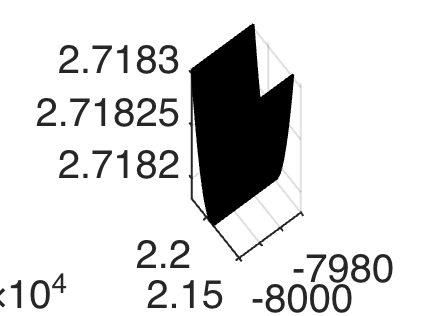


taou1 = -8.0000e+03:1:-7.6634e+03;
taor1 = 2.1498e+04:1:2.1804e+04;
[taou1,taor1] = meshgrid(taou1,taor1);
z1 = Q*exp(c1*prc+c2+c3*taor1-Tf1)+R*(aa*taou1.^2+bb*taou1+cc);
taou2 = -8.0000e+03:1:-7.6634e+03;
taor2 = 2.1804e+04:1:2.2110e+04;
[taou2,taor2] = meshgrid(taou2,taor2);
z2 = Q*exp(-c1*prc-c2-c3*taor2+Tf1)+R*(aa*taou2.^2+bb*taou2+cc);

figure()
surf(taou1,taor1,z1)

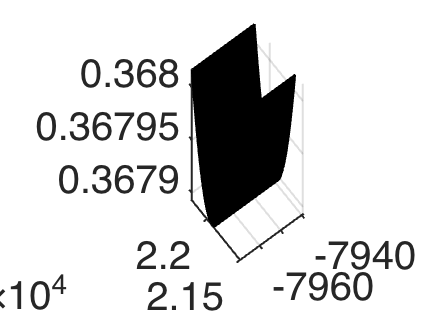

figure()
surf(taou2,taor2,z2)


% subplot(141)
% surf(taou1,taor1,z1)    %绘制三维表面图形
% hold on
% surf(taou2,taor2,z2)
% hold on
% plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
% hold on
% scatter3(point(:,1),point(:,2),point(:,3),'r','*');
% axis on;xlabel('X');ylabel('Y');zlabel('Z');
% title("z1","z2")
% 
% subplot(142)
% surf(taou1,taor1,z1)    %绘制三维表面图形
% hold on
% surf(taou2,taor2,z2)
% hold on
% plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
% hold on
% scatter3(point(:,1),point(:,2),point(:,3),'r','*');
% axis on;xlabel('X');ylabel('Y');zlabel('Z');
% title("z1","z2")
% view(0,90)
% 
% subplot(143)
% surf(taou1,taor1,z1)    %绘制三维表面图形
% hold on
% surf(taou2,taor2,z2)
% hold on
% plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
% hold on
% scatter3(point(:,1),point(:,2),point(:,3),'r','*');
% axis on;xlabel('X');ylabel('Y');zlabel('Z');
% title("z1","z2")
% view(0,0)
% 
% subplot(144)
% surf(taou1,taor1,z1)    %绘制三维表面图形
% hold on
% surf(taou2,taor2,z2)
% hold on
% plot3(point(:,1),point(:,2),point(:,3),'linewidth',1,'color','black')
% hold on
% scatter3(point(:,1),point(:,2),point(:,3),'r','*');
% axis on;xlabel('X');ylabel('Y');zlabel('Z');
% title("z1","z2")
% view(-90,0)
